# Izhikevich spiking model for cortical neurons (using ode45)

This live script is an attempt to reproduce the neuronal dynamics of most cortical neurons by using the Izhikevich model of spiking neurons. It is biologically as plausible as the Hodgkin-Huxley model, yet computationally viable like the integrate-and-fire models. For more information, please see the [original paper](http://www.izhikevich.org/publications/spikes.pdf) of Eugene Izhikevich [*IEEE Trans on Neural Networks, 14(6), 2003*] as well as his book, [Dynamical Systems in Neuroscience](https://www.izhikevich.org/publications/dsn.pdf). 

## 1 The spiking model

### 1.1 Spiking model equation of Izhikevich

The spiking model of cortical neurons is based on the following equations

$C\dot{v} =k\;\left(v-v_r \right)\left(v-v_t \right)-u+I$....................[1]

$\dot{u} =a\left\lbrace b\left(v-v_r \right)-u\right\rbrace$...................................[2] 

$\textrm{If}\;v\ge v_{\textrm{peak}} ,\textrm{then}$$v=c,u=u+d$.................[3]

From: Eugene M. Izhikevich (2007). *Dynamical systems in neuroscience: the geometry of excitability and bursting* (MIT Press).   pp. 273

To simulate the spiking model we first set up the differential equations symbolically and then solve the equations numerically.

clear
syms v(t) u(t) C k vr vt I a b vpeak c d dt Y
% Define first derivatives for u and v
DvDt      = diff(v);
DuDt      = diff(u);
% Set up differential equations for u and v
DE_v      = C*DvDt == k*(v - vr)*(v - vt) - u + I*heaviside(t - dt);
DE_u      =   DuDt == a*(b*(v - vr) - u);
% Convert the DE to a vector field
[DE_VF,~] = odeToVectorField(DE_v,DE_u);

At this point we are moving from the symbolic to the numeric world:

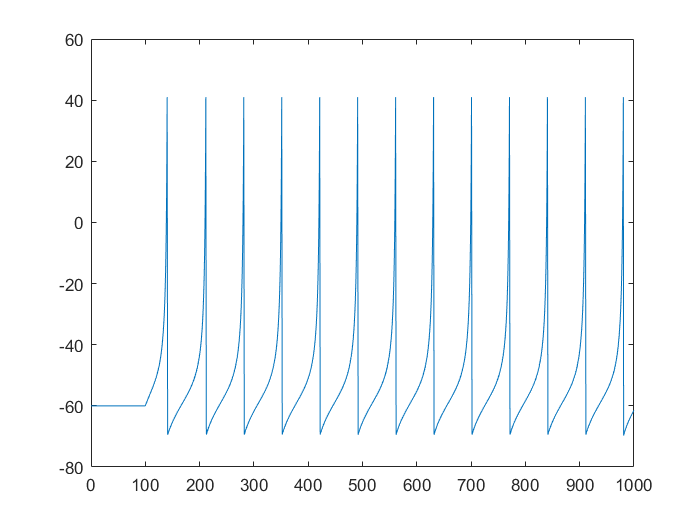

% ...and then, convert to a MATLAB function so we can integrate numerically
DE = matlabFunction(DE_VF,'vars',{t,Y,[C k vr vt a b vpeak c d I dt]});
% Define membrane...
params.mem.C     = 140;      % membrane capacitance
params.mem.k     = 0.7;
params.mem.vr    = -60;    % resting membrane potential
params.mem.vt    = -52;      % instantaneous threshold potential
params.mem.a     = 0.06;    % recovery time constant
params.mem.b     = -0.9;    % determines whether u is amplifying (b<0) or resonant(b>0)
params.mem.vpeak = 41;       % spike cutoff
params.mem.c     = -70;    % voltage reset value
params.mem.d     = 170;      % total outward-inward current during spike
% ...and stimulus parameters
params.stm.I          = 70; 
params.stm.dt         = 0;
params.stm.T          = 1000;
params.stm.pulseWidth = 0.9;
params.stm.dt         = params.stm.T*(1 - params.stm.pulseWidth);

% Set the simulation time and initial conditions
tspan = [0, params.stm.T];
IC    = [0, params.mem.vr];
tout  = tspan(1);
yout  = IC;
% ...and define the events function. This events function will help us keep
% track of the resets in the spiking model
options = odeset('Events',@events);

ie = 1;            % ie == 1 --> detect v >= vpeak, or, v - vpeak >= 0
while (ie ~= 2)    % ie == 2 --> detect tsim = T, or, tsim - T = 0
    [t,sol,~,~,ie] = ode45(DE,tspan,IC,options,[cell2mat(struct2cell(params.mem))',cell2mat(struct2cell(params.stm))']);
    
    tout  = [tout;   t(2:end)  ]; %#ok<*AGROW> 
    yout  = [yout; sol(2:end,:)];
   
    tspan = [tout(end), params.stm.T];             % adjust the simulation time
    IC    = [IC(2) + params.mem.d, params.mem.c];  % and set the values for v and u according to the spiking model
end

plot(tout,yout(:,2))

We use the events function to automatically detect zero crossings during integration. There are two different events we need to track, one for the Spiking model itself $(v \geq v_{peak})$, and one to stop the integration at $t=T$.

function [value,isterminal,direction] = events(t,y,pars)
vpeak      = pars(7);                % Back out the parameters for better readability 
T          = pars(12);
value      = [y(2) - vpeak; T - t];  % And then define the zeros that we need to detected

isterminal = [1;1];   % Stop the integration when zero is detected
direction  = [1;0];   % [Detect only zeros for increasing values; Detect all zeros]
end